clear all;
clc;
close all;

# Error analysis

We tried to find an explanation on why the FB DMD performs better for higher frequencies while the AugDMD performs worse

## Load data

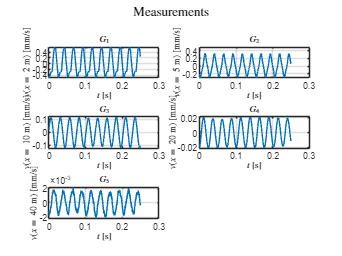

Seq = 2; % 1, 2 or 3

data = load("data\Seq"+num2str(Seq)+".mat");

numSamples = 50000;
window = 1:numSamples;

f = [data.G1V3(window)'; data.G2V3(window)'; ...
    data.G3V3(window)'; data.G4V3(window)'; data.G5V3(window)'];
time = data.Time;

dt = time(2)-time(1);
fs = 1/dt;
meas_points = [2 5 10 20 40];
% Plots
figure;
subplot(3,2,1)
plot(time(window),f(1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(1))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_1$','Interpreter','latex')

subplot(3,2,2)
plot(time(window),f(2,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(2))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_2$','Interpreter','latex')

subplot(3,2,3)
plot(time(window),f(3,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(3))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_3$','Interpreter','latex')

subplot(3,2,4)
plot(time(window),f(4,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(4))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_4$','Interpreter','latex')

subplot(3,2,5)
plot(time(window),f(5,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(5))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_5$','Interpreter','latex')
sgtitle('Measurements','Interpreter','latex')

## Alisaing analysis (comparison of FFT results for different sampling frequencies)

We check for aliasing effects. However these aren't the problem since we see that when we downsample the original signal, the same frequencies are still preserved. This means that by reducing the sampling frequency (reducing the effectivity of the FB-DMD) aliasing doesn't play a role

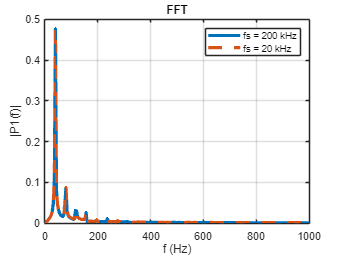

figure
Y = fft(f(1,:));
L = length(f);
Fs = 1/dt;
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f_fft = Fs/L*(0:(L/2));

plot(f_fft,P1,"LineWidth",3) 
hold on
downSampling = 100;
f_down = downsample(f(1,:), downSampling);

Y_down = fft(f_down(1,:));
time_down = downsample(time,downSampling);
L_down = length(f_down);
Fs_down = 1/(time_down(2)-time_down(1));
P2_down = abs(Y_down/L_down);
P1_down = P2_down(1:L_down/2+1);
P1_down(2:end-1) = 2*P1_down(2:end-1);
f_fft_down = Fs_down * (0:(L_down/2)) / L_down;

plot(f_fft_down,P1_down,"LineWidth",3,'LineStyle','--') 
grid on

title("FFT")
xlabel("f (Hz)")
ylabel("|P1(f)|")
xlim([0 1000])
legend({"fs = 200 kHz","fs = 20 kHz"})

## Autocorrelation

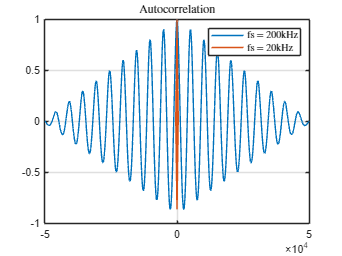

[acf_high, lags_high] = xcorr(f(1,:), 'coeff');
[acf_low, lags_low] = xcorr(f_down, 'coeff');
figure
plot(lags_high, acf_high); hold on;
plot(lags_low, acf_low); 
grid on
legend({'fs = 200kHz', 'fs = 20kHz'},'Interpreter','latex');
title('Autocorrelation','Interpreter','latex')

## Condition number comparison

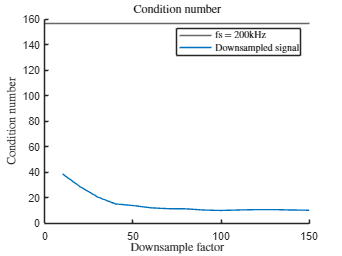

r = 5;
s = 50;

l = ceil((length(f))/2);

for i = 1:s
    f_aug([i s+i 2*s+i 3*s+i 4*s+i],:) = [f(1,i:l+i-1) ;f(2,i:l+i-1) ;...
        f(3,i:l+i-1) ; f(4,i:l+i-1) ; f(5,i:l+i-1) ];
end

X_aug_high = f_aug(:,1:end-1);

[U_high, S_high, V_high] = svd(X_aug_high, "econ");

% Truncate the SVD to the desired rank 'r'
Ur_high = U_high(:, 1:r);
Sr_high = S_high(1:r, 1:r);
Vr_high = V_high(:, 1:r);

% Build the low-rank approximation of the state transition matrix Atilde
% Atilde_Standard_high = Ur_high' * X_aug_high * Vr_high *Sr_high^(-1);

cond_aug_high = cond(Sr_high);


cond_low = [];

for downSampling = 10:10:150
    clear f_aug_down
    numSamples_down = numSamples/downSampling;
    window_down = 1:numSamples_down;
    
    G1 = downsample(data.G1V3,downSampling);
    G2 = downsample(data.G2V3,downSampling);
    G3 = downsample(data.G3V3,downSampling);
    G4 = downsample(data.G4V3,downSampling);
    G5 = downsample(data.G5V3,downSampling);
    
    f_down = [G1(window_down)'; G2(window_down)'; G3(window_down)'; G4(window_down)'; G5(window_down)'];
    
    l_down = ceil((length(f_down))/2);
    
    for i = 1:s
        f_aug_down([i s+i 2*s+i 3*s+i 4*s+i],:) = [f_down(1,i:l_down+i-1) ;f_down(2,i:l_down+i-1) ;...
            f_down(3,i:l_down+i-1) ; f_down(4,i:l_down+i-1) ; f_down(5,i:l_down+i-1) ];
    end
    
    
    
    X_aug_down = f_aug_down(:,1:end-1); X2_aug_down = f_aug_down(:,2:end);
    
    [U_down, S_down, V_down] = svd(X_aug_down, "econ");

    % Truncate the SVD to the desired rank 'r'
    Ur_down = U_down(:, 1:r);
    Sr_down = S_down(1:r, 1:r);
    Vr_down = V_down(:, 1:r);
    
    % Build the low-rank approximation of the state transition matrix Atilde
    % Atilde_Standard_down = Ur_down' * X_aug_down * Vr_down *Sr_down^(-1);

    cond_aug_low = cond(Sr_down);
    
    cond_low = [cond_low;cond_aug_low];
end
% cond_high = ones(length(cond_low),1)*cond_aug_high;
figure
yline(cond_aug_high)
hold on
plot(10:10:150,cond_low);
legend({"fs = 200kHz","Downsampled signal"},'Interpreter','latex')
xlabel('Downsample factor','Interpreter','latex')
ylabel('Condition number','Interpreter','latex')
title('Condition number','Interpreter','latex')


% disp(['Condition Number (High Sampling): ', num2str(cond_aug_high)]);
% disp(['Condition Number (Low Sampling): ', num2str(cond_aug_low)]);

